# **HW - separate audio mix using ICA**

Load mixed audio (save sample audio into ../data directory)

In this assignment, the number of audio sources is equal to mic (channels)

Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\dudql\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata) - new version 2.10 available
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit) - new version 5.5 available
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)


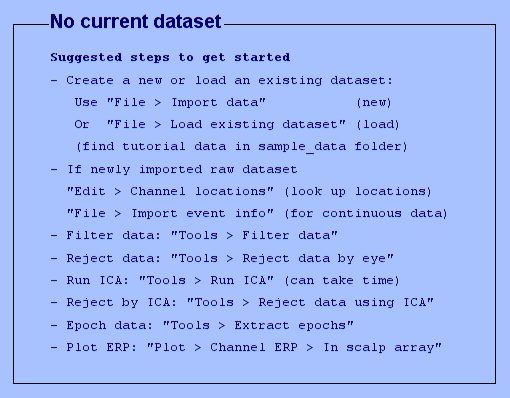

eeglab;

### Goals

- To estimate original audio soures through ICA

- To estimate mixing matrix wegiths (N by N matrix)

- To select corresponding sources that consists of the given audio mix and justify it (based on minimum error, highest correlation, comparing their spectrogram, etc.)

[X, fs] = audioread('./data/mixed_audio_2mix_v2.wav');  % X: (samples x channels)

disp('Mixed audio dimension:');

Mixed audio dimension:


disp(size(X));

    10625664           2



### Play the given audio mix

player = audioplayer(X, fs);
play(player)

### Stop playing

stop(player)

X = X';  % Transpose to (channels x samples)

## Run ICA runica() in EEGLAB (it could be slow)

% ================= Your code =========================)
ica = [];
[ica.weights, ica.sphere] = runica(X);  % ICA 수행


Input data size [2,10625664] = 2 channels, 10625664 frames/nFinding 2 ICA components using logistic ICA.
Decomposing 2656416 frames per ICA weight ((4)^2 = 10625664 weights, Initial learning rate will be 0.000937752, block size 81.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -0.999985 to 0.999985
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ...
step 1 - lrate 0.000938, wchange 0.23669479, angledelta  0.0 deg
step 2 - lrate 0.000938, wchange 0.00727070, angledelta  0.0 deg
step 3 - lrate 0.000938, wchange 0.00311060, angledelta 72.0 deg
step 4 - lrate 0.000844, wchange 0.00193728, angledelta 148.0 deg
step 5 - lrate 0.000760, wchange 0.00034194, angledelta 131.3 deg
step

### Normalize estimated sources

Your estimated souces should be [Nch x samples]

When your estimated sources are Xhat, normalization could be following:

% ================ Your code (refer to the lecture material)
% X_hat = ica.weights * ica.sphere * X;
ica.unmix = ica.weights * ica.sphere;
X_hat = ica.unmix * X;

% Normalization
X_hat = X_hat ./ max(abs(X_hat), [], 2);

### Play estimated source 1

player_estimated1 = audioplayer(X_hat(1, :), fs);
play(player_estimated1);

### Stop estimated source 1

stop(player_estimated1);

### Play estimated source 2

player_estimated2 = audioplayer(X_hat(2, :), fs);
play(player_estimated2);

### Stop estimated source 2

stop(player_estimated2);

### Your code - compare your estimated sources to the original sources and select which original sources were used to make the given audio mix

- Original sources can be downloaded in e-learning website

- Play and load each original sources

- Compare each original source to your estimated sources

- Answer two audio sources that consists of the given audio mix

- Demonstrate how similar your estimated sources and original sources through various methods (if data vector is too long, you can crop a part of data)

#### Load original source

audio_dir = './data/example_sound_sources/';
files = dir(fullfile(audio_dir, '*.wav'));

min_len = inf;
fs_all = zeros(length(files),1);
S = [];
for i = 1:length(files)
    [y, fs] = audioread(fullfile(audio_dir, files(i).name));
    y = y(:,1);  % mono 변환
    fs_all(i)=fs;
    min_len = min(min_len, length(y));
    S = [S; y'];  % 가로로 이어붙임 (후에 자름)
end

% 샘플링 레이트 통일 확인
if ~all(fs_all == fs_all(1))
    error('All audio files must have the same sampling rate');
end
fs = fs_all(1);

disp('Dimension of original source list');

Dimension of original source list


disp(size(S));

          11    10625664



### Downsampling for comparison - original source is too big to conduct correlation or visualization

%crop_len = fs * 30;  % 앞 30초만 비교
%down_xhat = X_hat(:, 1:crop_len);
%down_S = S(:, 1:crop_len);

down_xhat = resample(X_hat', 1, 48)';
down_S = resample(S', 1, 48)';
disp(size(S))

          11    10625664



#### Compare source 1 vs. original sources

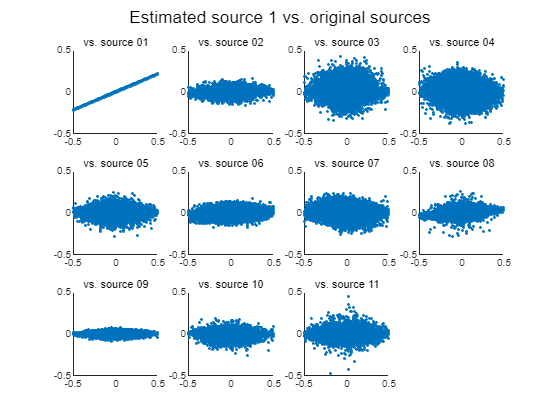

% Your Code
figure; clf;
for i = 1:size(S,1)
    subplot(3, 4, i);
    scatter(down_xhat(1, :), down_S(i, :), 5, 'filled');
    title(sprintf('vs. source %02d', i));
    xlim([-0.5, 0.5]); ylim([-0.5, 0.5]);
end
sgtitle('Estimated source 1 vs. original sources');

% Above image is instructor's example. You don't need to exactly replicate
% this example. It is not related to the current assignment - source 7 and
% 3 are not the answer of the current assignment.

#### Compare source 2 vs. original sources

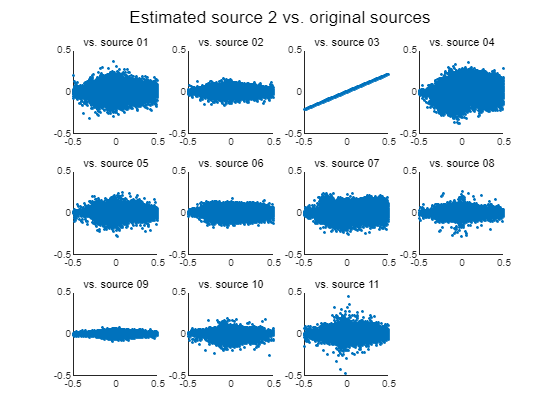

% Your Code
figure; clf;
for i = 1:size(S,1)
    subplot(3, 4, i);
    scatter(down_xhat(2, :), down_S(i, :), 5, 'filled');
    title(sprintf('vs. source %02d', i));
    xlim([-0.5, 0.5]); ylim([-0.5, 0.5]);
end
sgtitle('Estimated source 2 vs. original sources');

% Above image is instructor's example. You don't need to exactly replicate
% this example. It is not related to the current assignment - source 7 and
% 3 are not the answer of the current assignment.

## Export & submission

Export your estimated sources and upload to e-learning page

- Format: *.wav

- Matlab live scripts or Python scripts

### Notes

- ICA does not care order, magnitude, so estimated mixing matrix and original mixing matrix could look different.

% Check if X_hat is [n_sample x n_ch]

for i=1:size(X_hat, 1)
    fname = sprintf('./data/estimated_source%02d.wav', i);
    audiowrite(fname, X_hat(i, :)', fs);
end